*Andrea Perna                                                                                                                          Matriculation: 0001075631*

## **Exercise 1: Estimation**

The first part of the project deals with the estimation of an unknown linear model, in particular, we are asked to estimate the parameters and figure out the nature of such a model, that could be either ARX (Auto-Regressive eXogenous model) or FIR (Finite Impluse Response model). The identification procedure consists in different steps, however, the first approach to this kind of problem should always be the collection of data from the experiment. Once data have been properly collected, the next steps are respectively the design of the model structure Mp(Theta) (a fictitious model that would represent the stochastic behaviour of the system) and the choice of the estimation method. Then, a crucial step in the algorithm is held by the model complexity estimation, which uses some ad-hoc methods to find out the suitable number of paramaters p. Once the optimal model order has been recognize, then the estimation is performed and the model should pass through some validation methods, in order to validate it. A consistent model could be used to perform lot of tasks, e.g. prediction, diagnosis and control.

clear all
close all
addpath .\Functions;

### **1) UNDERSTAND THE MODEL STRUCTURE**

#### **1.1) DATA ACQUISITION**

The first step of the algorithm consists in the collection of samples data from the experiment. Input and output samples are respectively stored in the variables u and y. It is important to choose as many samples as possible, bacuse a large number of samples leads to higher efficiency of the estimator. Also, it allows us to talk about unbiasedness and consistency of the Least Squares estimation.

N=40000; %number of collected samples
Student = 'Andrea Perna';
Matriculation = '0001075631';
[Measurements] = IdentifyThis(N, Student, Matriculation);

%full data-set
u=Measurements.u;
y=Measurements.y;

Output samples could be visualized in the the figure below. Since both the order and the type of the stochastic model are unknown, the goal of the Learning from Data algorithm should be to identify those characteristics and to provide a competent model structure that describes the following observations. 

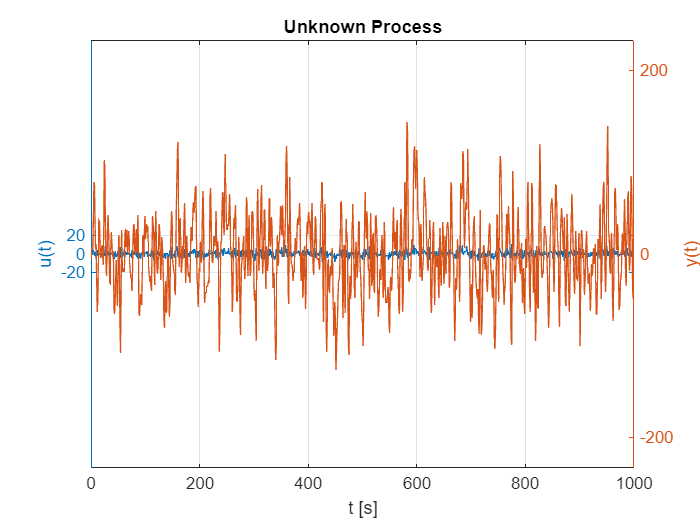

%unknown process'plot
figure();
time=[0:1:N-1]';
ax=plotyy(time(1:1000),u(1:1000),time(1:1000),y(1:1000));
grid on;
ylabel(ax(1), 'u(t)');
ylim(ax(1),[-max(y)*1.5 max(y)*1.5]);
ylabel(ax(2), 'y(t)');
ylim(ax(2),[-max(y)*1.5 max(y)*1.5]);
xlabel('t [s]');
title('Unknown Process');

It is possible to recognize a significant presence of noise in the output measurements with respect to the applied input samples. We need to estimate the proper model order for such stochastic disturbances affecting the measurements.

#### **1.2) CHOICE OF THE MODEL STRUCTURE**

Since it is tough to figure out the nature of the dynamic model at a first glance, that could be either ARX or FIR, we decide to perform the whole estimation procedure for both of them. In fact, we will surely be able later on to understand which is the more suitable model structure that is able to describe the set of considered I/O data.The main difference between an ARX and a FIR model, is that the second one has no auto-regressive part, that is its input disturbance could be considered as a simple zero mean white noise. This type of model has got an impulse response of finite duration that settles to zero in finite time. Hence, differently than the ARX model, The Finite Impulse Response one doesn't contain the previous output samples. Both of them consist also in the sum of a deterministic part  (given by the input sequence u) and a stochastic disturbance d. However, since the disturbance is stochastic, the overall model turns out to be stochastic as well. Here a scheme of the two model structures, respectively ARX and FIR:

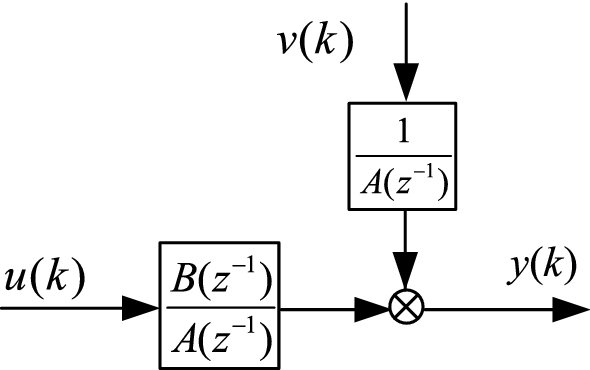                                            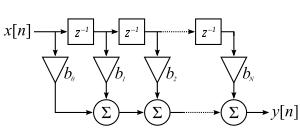

### **2) DEFINE THE REQUIRED ESTIMATION ALGORITHM**

The algorithm that has been choosen in order to estimate the final model is Least Squares, that is a well-kwown method able to approximate the solution of an overdetermined system by minimizing the sum of the squares of the residuals (the so-called loss function J). The latter are the difference between the real ouput observations and the estimated coefficients. It turns out to be a consistent estimator, and also unbiased for some models like FIR. A the end of the procedure, we are going to obtain a vector ThetaHat containing all the estimated parameters of the model.

#### 
$$J(\hat\theta)=\sum_{t=1}^N \epsilon^2(t)=\epsilon^T\epsilon=\|\epsilon\|^2
$$
                    
$$\varepsilon=[\varepsilon(1) \varepsilon(2) \ldots \varepsilon(N)]^{T}$$


As previously mentioned, Least Squares Estimation must be performed by considering the system both as ARX and FIR. However, the final estimation that is ready to face the validation step will be performed only after having understood the proper model order. The final estimation ThetaHat is different in the two cases and it depends on the expression of the so-called Hankel Matrix, which is calculated in the ad-hoc function myHank.m. The two formula are written below, respectively for the ARX and FIR models:

#### 
$$\hat{\theta}=\left(\frac{H^{T} H}{N}\right)^{-1} \frac{H^{T} Y}{N}=\left(\frac{1}{N} \sum_{t=1}^{N} \varphi(t) \varphi^{T}(t)\right)^{-1} \frac{1}{N} \sum_{t=1}^{N} \varphi(t) y(t)$$


#### 
$$\hat{\theta}=\left({Hu^{T} H}\right)^{-1} {Hu^{T} Y}=\left( \sum_{t=1}^{N} \varphi(t) \varphi^{T}(t)\right)^{-1} \sum_{t=1}^{N} \varphi(t) y(t)$$


The matlab function that have been developed in order to perform Least Squares is *myLS.m*. It is basically composed of a* swicth-case statement*, that is able to discriminate between the two types of model structures under consideration (it could be easily extended for possible future implementations). Each sub-case computes its own Hankel matrix of the regressors by calling the function *myHank.m*, then it evaluates the result (res) of the estimation by computing the ThetaHat vector of parameters. In FIR models the Hankel matrix is composed by only the matrix containing past input samples, while in the ARX model the Hankel matrix should contain both past input and output samples.

As an example, let's try to evaluate the estimated parameters of the unknown process by using an ARX model of order n=3. We we expect a model with six parameters (2*p). However, this could not be the best achievable model, we have are only assuming an order. The next step of the procedure should be, in fact, the model order estimation.

%estimated ARX
ThetaHatTry = myLS(y,u,3,'ARX') %my Matlab routine

ThetaHatTry =    -0.4704
    0.1543
   -0.0294
    6.2494
    7.0784
    1.4985


%true ARX
Hu = myHank(u,3);
Hy = myHank(y,3);
H = [-Hy,Hu];
disp(lsqr(H,y(4:end))); %official Matlab routine

lsqr stopped at iteration 6 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 6) has relative residual 0.0029.
   -0.4704
    0.1544
   -0.0294
    6.2494
    7.0784
    1.4985



### **3) ESTIMATE THE MODEL ORDER**

The main goal of this step of the Identification algorithm is to figure out which is the best suitable model order that is able to describe the data correctly. An important concept to bear in mind during the model order estimation is the Occam's Razor (a.k.a.Parsimony Principle), which claims that: *out of the competent models which explain well the data, the one with smallest complexity should be chosen*. There are several methods to estimate the optimal order of a model. 

`1)` We can divide the data-set into two parts: the Training Set, which is used to learn the model, and the Validation Set, that consists in unseen data for the system. By using this approach, we could have a good guess of a suitable order by simply looking for the minimum point of the loss function J, which will coincide with the desired value of p. However, this method would not give us good results in such a case.

`2)` We can still use the Training Set without dividing the data points, by using some criteria with complexity terms. We are going to use FPE and MDL for the model order estimation.

`3)` We can use the only the Training Set and look for a stabilization of the loss function J. However, this solution is correct only if we are in a simulation environment and lot of data have been collected. Since we are in matlab environment we could have a look at J to recognize a stabilizing effect. 

#### 3.1) STABILIZING EFFECT OF THE LOSS FUNCTION

Let's plot the cost function in the training set. For this purpose, the function* myCostFunc.m* is used, which computes the value of J for both the model cases, depending on the choice of the input parameter *type*. It computes the difference between the measured output values y and the estimated ones, that are computed as the product of the Hankel and ThetaHat matricies. To plot the cost function, let's cycle for the first model orders, our aim is to look at a stabilizing effect:

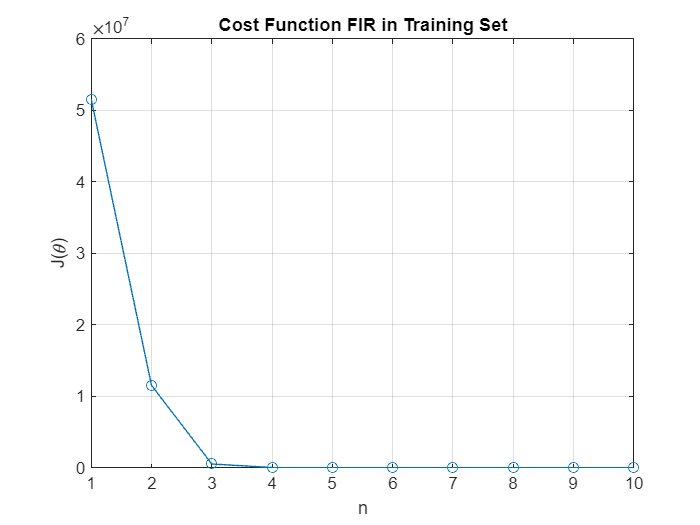

%FIR model
L  = 10;
J = zeros(L,1);
for n=1:L
    Theta_TS = myLS(y,u,n,'FIR');
    J(n) = myCostFunc(y,u,Theta_TS,'FIR');

end
figure();
plot(J,'-o');
grid on
ylabel('J(\theta)');
xlabel('n');
title('Cost Function FIR in Training Set');

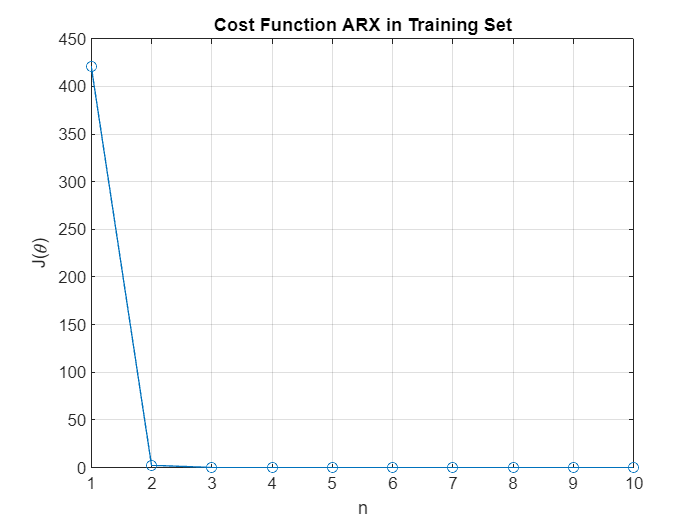

%ARX model
J = zeros(L,1);
for n=1:L
    Theta_TS = myLS(y,u,n,'ARX');
    J(n) = myCostFunc(y,u,Theta_TS,'ARX');

end
figure();
plot(J,'-o');
grid on
ylabel('J(\theta)');
xlabel('n');
title('Cost Function ARX in Training Set');

It is possible to conclude that the FIR model would be of order 4, whereas the ARX model vould be of order 3. These conclusions come from the fact that we working in a simulation environment, that is a true order does exist. However, let's try to prove these conclusions by looking at other methods.

nARX=3;
nFIR=4;

#### **3.2) METHODS WITH COMPLEXITY TERM IN TRAINING-SET**

Let's apply two of the most famous model order estimation methods to the whole data-set. They could help us in understanding the correct order of the stochastic model thanks to the penalizing effect that they give to the cost function J(Theta), which is computed by the matlab function *myCostFunc.m*.

#### **3.2.1) FPE**

Akaike Final Prediction Error is a method that provides a measure of model quality by simulating the situation where the model is tested on different data sets, It turns out that the model with the smallest FPE is the best one. This algorithm has been implemented in the matlab function *myFPE.m*, that gives as an output the value FPE, computed as the sum of the loss function J and a proper penalty term (2*p)/N. This latter term represents a penalty for high complexity solutions, it is a mathematical application of the Parsimony Principle.  To figure out which is the best order for the model, we can try to plot a graph of the FPE values for all the Least Squares Estimations within a given range of orders. Let's have a look at the plot for the estimations from 1 to 20.

We start with the application of FPE for the model, as assumed to be *ARX*:

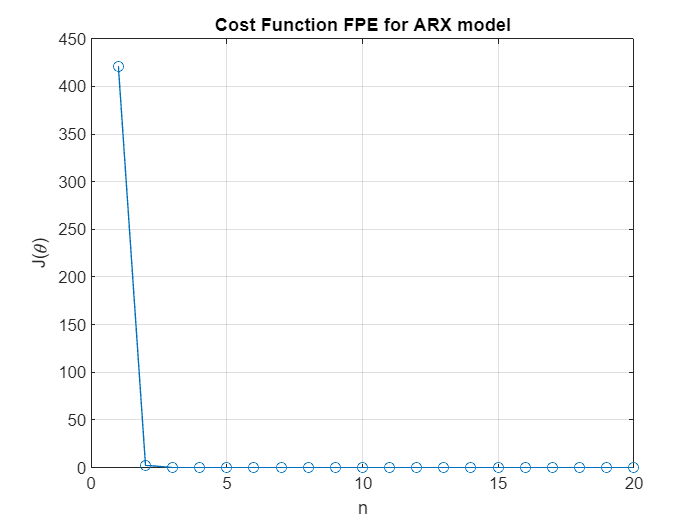

L=20;
for n=1:L
    Theta_ARX=myLS(y,u,n,'ARX');
    J(n)=myFPE(y,u,Theta_ARX,'ARX');
end

figure();
plot(J,'-o');
grid on;
hold on;
ylabel('J(\theta)');
xlabel('n');
title('Cost Function FPE for ARX model');

Unfortunately it is not easy to see the method's effect, so instead of evaluating the FIR case with such a method we'd like to use a better one to try to visualize the penalizing effect. It is also possible to apply Akaike Information Criterion (AIC), which has been properly developed inside the function *myAIC.m*. However, results of that algorithm won't be shown, because they are very much alike FPE ones.

#### **3.2.2) MDL**

Minimum Description Length is undoubtedly one of the best model estimation methods, it is a sort of optimal application of the Parsimony Principle. It consists of a sum of the loss function J and a penalty term, as for the FPE algorithm. However, it penalizes more the loss function because of the presence of the logarithm inside the penalty term. This method has been developed inside the function *myMDL.m*, which is structurally similar to *myFPE.m.* In fact, it calls the function *myCostFunc.m* that computes the loss function.

#### 
$$MDL=N*log(J(\hat\theta_n))+ 2p*log(N)$$


Let's apply the method for the model considered as an *ARX* process:

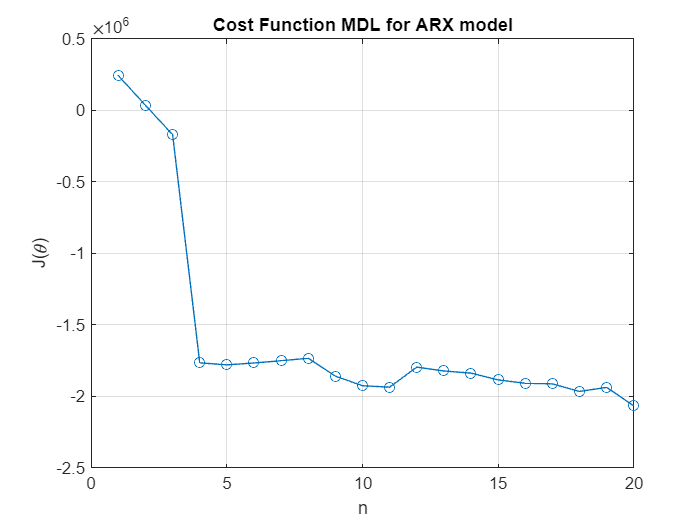

L = 20;
J = zeros(L,1);
for n=1:L %range of model orders to evaluate
    Theta_ARX=myLS(y,u,n,'ARX');
    J(n)=myMDL(y,u,Theta_ARX,'ARX');
end

figure();
plot(J,'-o');
grid on;
hold on;
ylabel('J(\theta)');
xlabel('n');
title('Cost Function MDL for ARX model');

Let's account now for the application of MDL on the *FIR* model:

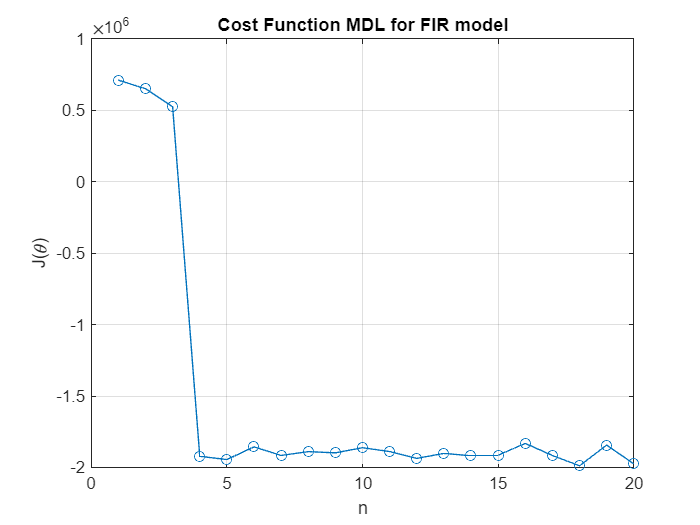

J = zeros(L,1);
for n=1:L %range of model orders to evaluate
    Theta_FIR=myLS(y,u,n,'FIR');
    J(n)=myMDL(y,u,Theta_FIR,'FIR');
end

figure();
plot(J,'-o');
grid on;
hold on;
ylabel('J(\theta)');
xlabel('n');
title('Cost Function MDL for FIR model');

We start recognizing the true order of the FIR structure (which is 4), however, let's try to use another method.

#### **3.3) METHODS WITH COMPLEXITY TERM IN VALIDATION-SET**

Since the behaviour is not so clear we'd like to split the data-set into two parts: the *Training Set*, that is used to estimate the model Theta and the *Validation Set*, which is instead used to predict the order of the model. Let's account for MDL in the **Validation Set**, we start from the *ARX* model:

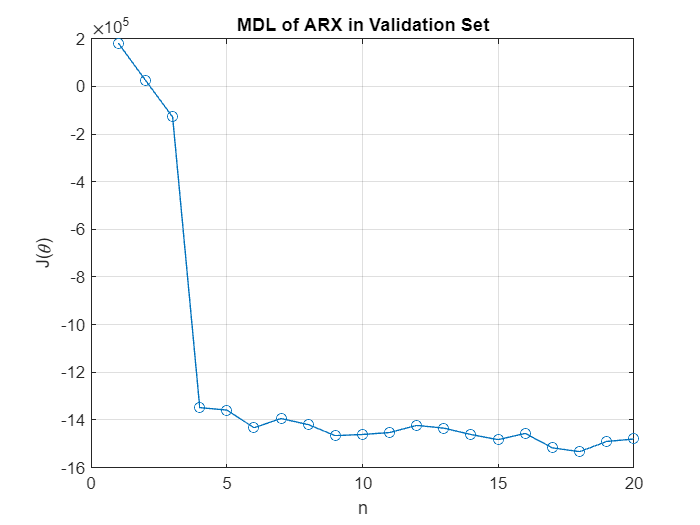

%training set
uTS = u(1:round(N/4));
yTS = y(1:round(N/4));

%validation set
uVS = u(round(N/4)+1:end);
yVS = y(round(N/4)+1:end);

L = 20;
J = zeros(L,1);

for n=1:L %range of model orders to evaluate
    Theta_ARX = myLS(yTS,uTS,n,'ARX');
    J(n)=myMDL(yVS,uVS,Theta_ARX,'ARX');
end
[value,n_min] = min(J);
nARXx = n_min;

figure();
plot(J,'-o');
grid on;
hold on;
ylabel('J(\theta)');
xlabel('n');
title('MDL of ARX in Validation Set');

and finally we evaluate the FIR model:

for n=1:L %range of model orders to evaluate
    Theta_FIR_VS = myLS(yTS,uTS,n,'FIR');
    J(n)=myMDL(yVS,uVS,Theta_FIR_VS,'FIR');
end
[value,n_min] = min(J);
nFIRx = n_min

nFIRx = 8

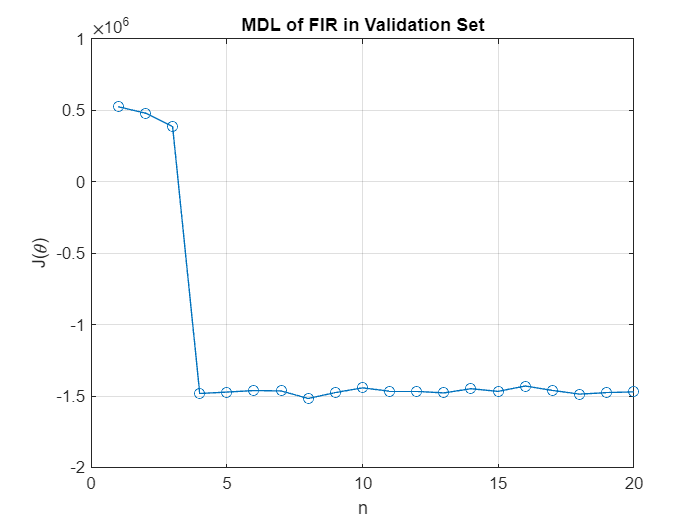

figure();
plot(J,'-o');
grid on;
hold on;
ylabel('J(\theta)');
xlabel('n');
title('MDL of FIR in Validation Set');

Unfortunately the behavior is still not so clear. However, it is possible to recognize the true order in the last FIR model, that is 4. The MDL penalization, in fact, tends to rise up the cost function as n increases. We should pick the model order to be as small as possible in order to follow the Occam's Razor, by always remembering to avoid overfitting. Now we are able to proceed with the validation procedure by knowing which is the proper order of the two models that we are looking for.

### 4) VALIDATE THE MODEL

The last step of the learning from data flowchart is represented by Model Assessment (Validation), it consists in evaluating the capability of the final model to describe to describe the process that has generated the data, by obviously taking into account the purpose of such an estimation. We rely on two basic assumptions, the estimated model asymptotically converges to the true one and in that case we get the sequence of residuals strictly similar to a zero-mean white process. Therefore, starting from I/O data and residuals we'd like to prove that:

**-> ****The sequence of residuals Eps(t,ThetaHat) is a zero-mean white process**

***-> ******The sequence of residuals Eps(t,ThetaHat) is uncorrelated with the input signal u(t)***

To perform model validation we use both whiteness and cross-correlation tests, that are going to analyze the residuals in order to check whether the model is competent or not. They could be performed by means of *Statistical Hypothesis Testing*, either Chi-Squared or Guassian tests. 

#### **4.1) EVALUATION OF THE TRUE MODEL STRUCTURE**

At this point the best suitable order of the model is no longer unknown, so we can compute the Least Squares Estimation for both the analyzed model structures:

%Estimation of optimal ARX and FIR models with the whole data-set
ThetaHat_ARX=myLS(y,u,nARXx,'ARX')

ThetaHat_ARX =    -1.4113
    1.2830
   -0.9541
    0.6400
   -0.4113
    0.2639
   -0.1727
    0.1156
   -0.0782
    0.0526


ThetaHat_FIR=myLS(y,u,nFIRx,'FIR')

ThetaHat_FIR =     6.2494
   10.0185
    5.2470
    1.1073
    0.0000
    0.0000
    0.0000
    0.0000


It is possible then, from the knoledge of the optimal Least Squares estimations for ARX and FIR models, to compute the values of the residuals by taking the difference between real and predicted values of the output. This is a crucial aspect, because it leads us to figure what is the actual structure of the stochastic model of the data. In fact, the correct model's stucture is going to be the one with smallest values of residuals, which means to have a line that correctly describes the given data by minimizing the errors as much as possible. An important thing to notice is that some of the estimated parameters of the ARX and FIR models are practically equal to zero. Therefore, we could have a look at the residuals by considering the true model order that we have found out at the point 3.1) of the project by following the Parsimont Principle. Let's have a look at the values of the residuals:

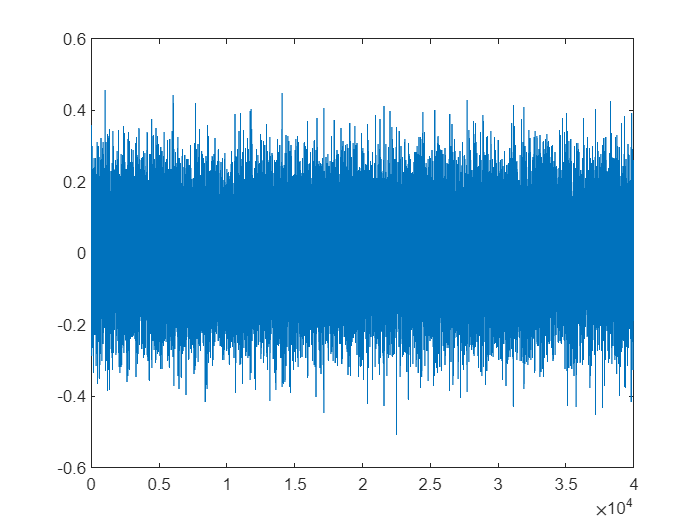

%computation of residuals for the ARX model
ThetaHat_ARX=myLS(y,u,nARX,'ARX');
resARX = residuals(y,u,ThetaHat_ARX,'ARX');
figure();
plot(resARX);

%computation of residuals for the FIR model
ThetaHat_FIR=myLS(y,u,nFIR,'FIR')

ThetaHat_FIR =     6.2494
   10.0185
    5.2470
    1.1073


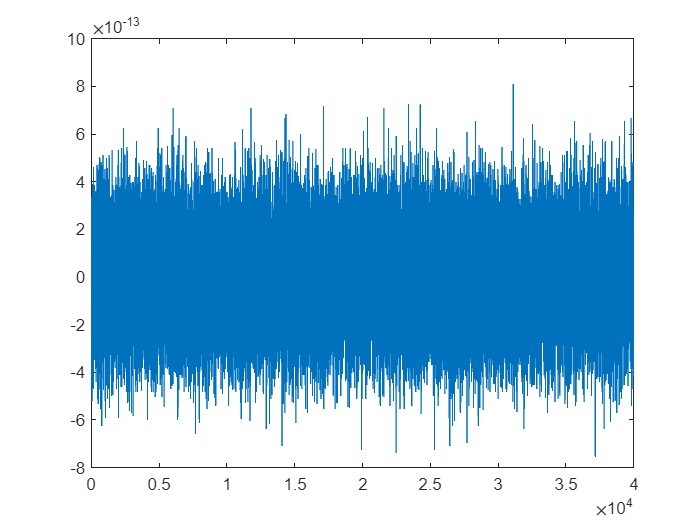

resFIR = residuals(y,u,ThetaHat_FIR,'FIR'); 
figure();
plot(resFIR);

It is clear that the stochastic model that well-represents the project's data is a **Finite** **Impulse Response Model**. Residuals, in fact, are definitely lower in the FIR model. Since we know what is the actual model's structure we can proceed with the actual validation step, to finally assess the model.

#### **4.2) WHITENESS TEST**

The goal of such a test is to figure out whether the sequence of residuals is a zero mean white process, which means that there are no remarkable patterns across such a sequence. We need to perform a Binary Statistical Hypothesis Testing onto the sequence of residuals from the ***FIR model*** that we have just obtained:

**H0: Eps(t,ThetaHat) is zero mean white process;**

**H1: not H0;**

To perform such a test we need samples of autocorrelation of the residuals. There are mainly two ways to check the residuals' whiteness, we are going to use m guassian testsfollowed by the Anderson test, to take the final decision.

**4.2.1) Whiteness Test in Training-Set**

We would like to perform the whiteness test by using the whole data-set. On the one hand we need to fix the size of the test alpha (also called significant level or p-value), that constitutes the threshold for a competent model. It represents the first type of error, that is the probability to accept H1 such that H0 is true. On the other hand we fix the number of gaussian tests m in a range from 5 to N/4, for this project we go for m=N/4. We need m samples of the normalized autocorrelations of the residuals, for each of them we are going to perform a gaussian test in order to prove the rightness of the first hypothesis. For this purpose, a proper matlab function *guassianTest.m* has been properly developed, which basically compare the value of x (computed as the ratio between vector of sample autocorrelations and the variance) with a value related to alpha. At the end of the cycle, the fuction *andersonTest.m *will compute the ratio betwen failed and succeded tests to take the final decision about the whiteness of the residuals' sequence.

alpha = 0.1; %significant level for the tests, we use common sense

N=length(y)-nFIR; %number of data points
m = round(N/4); %number of guassian tests

normalizedACF = autocorr(resFIR, m); %normalized autocorrelation of residuals

%take m gaussian tests
m_bar = 0;
for i=2:m
    if (gaussianTest(N,normalizedACF(i),alpha) == false)
        m_bar = m_bar + 1;
    end
end

%Anderson test to take the final decision
if (andersonTest(m,m_bar,alpha) == true)
    disp("passed.");
    disp(m_bar);
    disp(m_bar/m);
    WT1 = true;
else 
    disp("failed.");
    disp(m_bar);
    disp(m_bar/m);
    WT1 = false;
end

passed.


   688



    0.0688



**4.2.2) Whiteness Test by means of Cross-Validation**:

%training set
uTS = u(1:N/2);
yTS = y(1:N/2);
%validation set
uVS = u(N/2+1:end);
yVS = y(N/2+1:end);

%Estimation of FIR's model and residuals
ThetaHat_FIR_CV=myLS(yTS,uTS,nFIR,'FIR');
resFIR_CV = residuals(yVS,uVS,ThetaHat_FIR_CV,'FIR');

N=length(yVS)-nFIR; %number of data points
m = round(N/4);

normalizedACF_CV = autocorr(resFIR_CV, m); %normalized autocorrelation of residuals

%take m gaussian tests
m_bar = 0;
for i=2:m
    if (gaussianTest(N,normalizedACF_CV(i),alpha) == false)
        m_bar = m_bar + 1;
    end
end

%Anderson test to take the final decision
if (andersonTest(m,m_bar,alpha) == true)
    disp("passed.");
    disp(m_bar);
    disp(m_bar/m);
    WT2 = true;
else 
    disp("failed.");
    disp(m_bar);
    disp(m_bar/m);
    WT2 = false;
end

passed.


   318



    0.0636



WT = WT1 | WT2;
if WT
    disp("Whiteness test passed. Eps is a zero mean white noise.");
else
    disp("Whiteness test failed. Eps is not a zero mean white noise.");
end

Whiteness test passed. Eps is a zero mean white noise.


There is also a matlab function called* chi2Test.m* in the *Functions* folder, that could be used in order to perform the Whiteness Test by means of the Chi-square statistical hypothesis testing. This latter routine basically computes the Xsquare value from the Chi-square distribution table by means of the knoledge about alpha and the degree of freedom m. Then, it compares this value with the proper x value that should be computed out of the function. It has got the same outcome of the whiteness test. At the end, we obtain a valid outcome for the whiteness test.

#### **4.3) CROSS-CORRELATION TEST**

The goal of such a test is to figure out whether the sequence of residuals uncorrelated with the input sequence u(t). Even in this case, a Binary Statistical Hypothesis Testing is needed:

**H0: Eps(t,ThetaHat) is uncorrelated with u(t);**

**H1: not H0;**

To perform the test we need to obtain the crosscorrelation between residuals and input samples. Similarly to the whiteness test, also the cross-correlation test could be performed by means of m guassian tests. However, we'd like to prove the results through of the chi2 statistical hypothesis testing.

**4.3.1) Cross-Correlation Test in Training Set**

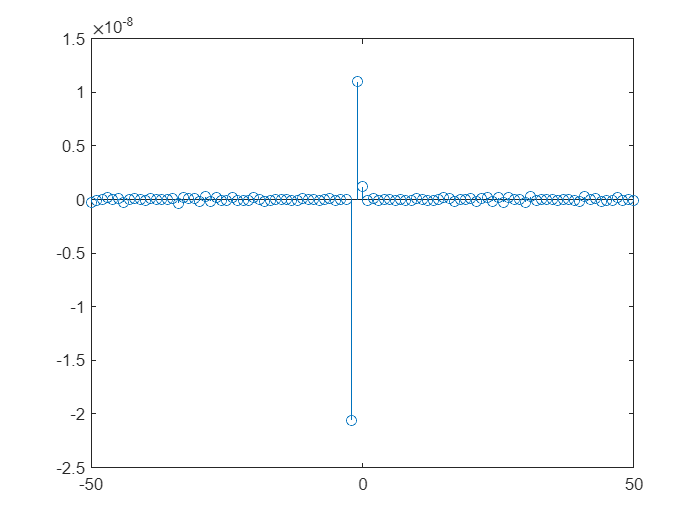

N=length(y)-nFIR; %number of data points
m = round(N/4); 

%cross-correlation between input and residuals samples
[xCorrEpsU,lags] = xcorr(resFIR,u,50); 

%plot of the cross-correlation samples
figure();
stem(lags,xCorrEpsU);

It is possible to see from the plot that *there is no meaningful correlation between input and residuals*, this consideration could just be enough to conclude that they are actually uncorrelated. However, let's prove the result by means of the Statistical Hypothesis Testing, in particular we go for the Chi-square test. The function *chi2Test.m *provides the result of the Chi2 test by comparing the x value shown above and the Xsquare from the Chi2 table.

[ACF, delay] = autocorr(resFIR, m);
sigma = diag(u(nFIR+1:end)'*u(nFIR+1:end))/N;
varEps = ACF(1);
ACF = ACF(2:end);
x = N*(ACF'*(1/sigma)*ACF)/(varEps^2);
if chi2Test(x,m,alpha)
    disp("Cross-correlation test passed. Eps and u are uncorrelated.");
else
    disp("Cross-correlation test failed. Eps and u are correlated.");
end

passed


Cross-correlation test passed. Eps and u are uncorrelated.


#### **4.4) COMPARISON BETWEEN TRUE AND ESTIMATED OUTPUT SAMPLES**

This last test ends the System Identification procedure. If both the tests have correctly been passed, then the model is accepted and we have a competent model. This latter, could be used in various applications like *control*, *diagnosis*, *weather forecasting*, *interpretation* and so on. If instead the model was not accepted, then something should be changed, for instance a different model order or even a different model structure for data. To give a** last brief proof of the model's goodness**, we can plot together the real and estimated output (these latter are the predictions), let's see the result:

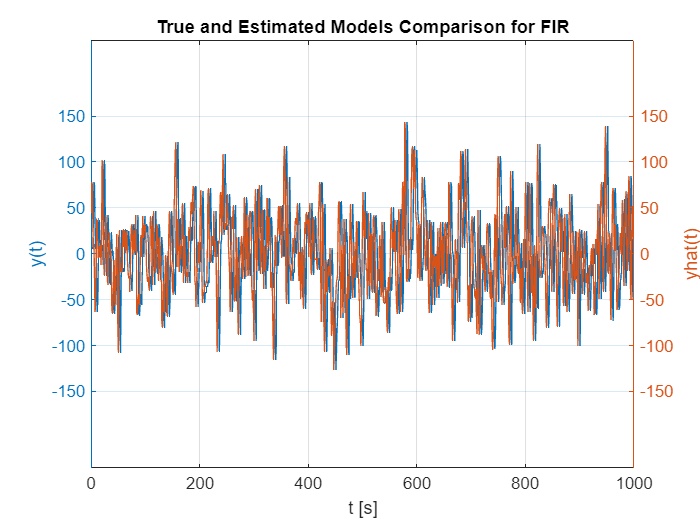

%computation of estimated output
resFIR = residuals(y,u,ThetaHat_FIR,'FIR');
yhat = y(nFIR+1:end) - resFIR;

%plot of the comparison
figure();
time=[0:1:N-1]';
ax=plotyy(time(1:1000),y(1:1000),time(1:1000),yhat(1:1000));
grid on;
ylabel(ax(1), 'y(t)');
ylim(ax(1),[-max(y)*1.5 max(y)*1.5]);
ylabel(ax(2), 'yhat(t)');
ylim(ax(2),[-max(y)*1.5 max(y)*1.5]);
xlabel('t [s]');
title('True and Estimated Models Comparison for FIR');

Since differences between real output values and estimated predictions are practically indistinguishable, we could conclude that the estimated FIR model is a competent model for the given set of data.

## **Exercise 2: Classification**

In this second half of the project we deal with the classification problem with probabilistic models by means of the Logistic Regression technique. This method tries to estimate the posterior probabilities of the observations P(Ci|u(t)), that are the probabilities of the input values to belong to a certain class, by means of the estimation of an hyperplane. This latter, in fact, is estimated in order to maximize the probability of getting correct labels:

#### 
$$\beta_{0}+\beta_{1} u_{1}(t)+\beta_{2} u_{2}(t)+\cdots+\beta_{r} u_{r}(t)=0$$


#### $\varphi^{T}(t) \theta=0$ with $\varphi(t)=\left[1 \quad u_{1}(t) \quad u_{2}(t) \quad \cdots \quad u_{r}(t)\right]^{T}
$ and $\theta=\left[\beta_{0} \quad \beta_{1} \quad \cdots \quad \beta_{r}\right]^{T}$

In particular, we model such a probability by means of the so-called *Logistic Sigmoid Function*, as shown below. This important function has been properly developed inside the matlab script *Sigmoid.m*.

#### 
$$f(z)=P(C1|u(t))=\frac{e^{z}}{1+e^{z}}=\frac{1}{1+e^{-z}}$$
                    
$$1 -f(z)= P(C2|u(t))=\frac{1}{1+e^{z}}$$


clear all
close all
addpath ./Functions;

### 1) UNDERSTAND THE FEATURE SET IN SPACE

We start accounting the problem by collecting N data-points. Our goal would be to clarify their configuration in space, to figure out whether there exist one or multiple linear boundaries able to perfectly divide them. 

N=10000; %number of collected data
Student = 'Andrea Perna';
Matriculation = '0001075631';

We decide to divide the data-set into two parts: a *feature set*, which is used to learn the optimal linear decision boundary to classify the input points and a *test set*, which instead is used to validate the classifier with unseen data for the problem.

[FeatureSet] = ClassifyThose(N,Student,Matriculation);
Utrain  = FeatureSet.Utrain;
Ytrain  = FeatureSet.Ytrain;
Utest   = FeatureSet.Utest;
Ytest   = FeatureSet.Ytest;

Let's plot the training data points in order to correctly visualize them:

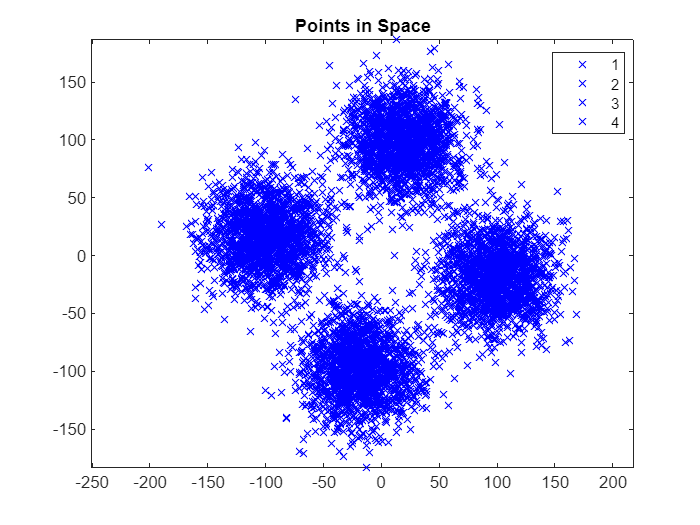

figure();
gscatter(Utrain(:,1),Utrain(:,2),Ytrain,'b','x');
title('Points in Space');
axis equal

Let's distinguish the points in space according to their Y labels, we are using the official matlab function *gscatter.m* to visualize the results:

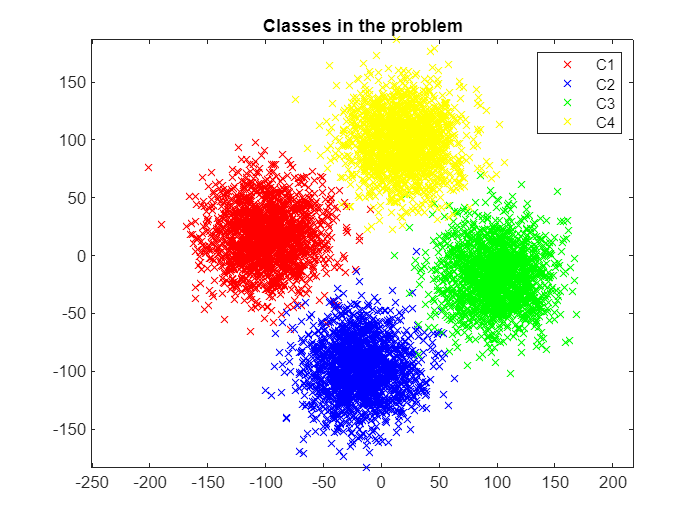

figure();
gscatter(Utrain(:,1),Utrain(:,2),Ytrain,'rbgy','x');
title('Classes in the problem');
legend({'C1','C2','C3','C4'});
axis equal

We can easily see that we are in a multi-class problem, therefore we are interested to discriminate between more than two classes. For this purpose we are still interested in using the Logistic Regression, in particular we deal with **One-Vs-All** (or **One-Vs_TheRest**) approach. This method works as follows: M binary classification problems are deviced (where M is the number of classes) by means of the estimation of M linear decision boundaries. Each of them will be the discriminant function between the specific class and all the other ones. At the end of the procedure we are going to be able to estimate M posterior probabilities and the largest one will finally decide the class for the new input u(t). We need a smart way to divide the data in order to have M binary classification problems. 

%Binary classifications' definitions
YtrainC1 = binaryClassification(Ytrain,Utrain,1);
YtrainC2 = binaryClassification(Ytrain,Utrain,2);
YtrainC3 = binaryClassification(Ytrain,Utrain,3);
YtrainC4 = binaryClassification(Ytrain,Utrain,4);

The matlab function *binaryClassification.m* deals with the creation of a new column vector Ytrain that acts as a discriminant between the specific input class and the others. It basically assigns 1 in correspondence to the value *i* of the class C*i* and 0 in all the other cases. Now we are able to treat the problem with Logistic Regression by following a Multi-Class Approach.

### **2) DEFINE THE REQUIRED CLASSIFICATION ALGORITHM**

The algorithm that is taken into account in this project for the classification is the *Newton-Raphson method*. It is one of the most famous optimization algorithms, used in a variety of Machine Learning applications. In a nuthshell, it is able to find the local minima of a differentiable function (that in our case is the loss function J) by iteratively approximating such a function with its second order Taylor approximation and going towards the minumum. It basically follows the Newton's direction, which can be seen as the correction of the gradient by means of the hessian of the loss function, it represents the direction of maximum decrease of the function at the evaluated point. The Loss Function that we have to maximize is shown above. Hnece, we'd like to minimize $-J$ with the Newton-Raphson optimization algorithm.

#### $J(\theta)=\log P(Y \mid \theta)=\sum_{t=1}^{N}[y(t) \log f(z(t))+(1-y(t)) \log (1-f(z(t)))]$.

The Newton-Raphson method has been properly developed inside the matlab function *NewtonRaphson.m*. This latter deals with the update of the model Theta until the achievement of the stopping criterion, that is the point in which we have a fair enough optimization of J. At each iteration, in fact, the actual model Theta of the line z(t) is changed by means of the effects of hessian and gradient, that are respectively computed inside the matlab function *LRCostFuncDeriv.m. *This latter routine contains a switch-case statement that is able to compute either the gradient (as Phi'*(F-Y)) or the hessian (as Phi'*W*Phi), according to the input desired order of the derivative. The cost function J itself, instead, is computed inside the proper matlab function *myLRCostFunc.m*. Tthe above shown expression of J is implemented there, the probability f(z) is computed accordingly inside the function *Sigmoid.m*. For a better explanation, the whole structure of the Netwon-Raphson method is shown below. However, the proper function *NewtonRaphson.m *will be called in lieu of this code later on. Let's have a look at the estimation of the optimal hyperplane for the binary classification problem between C1 and the rest:

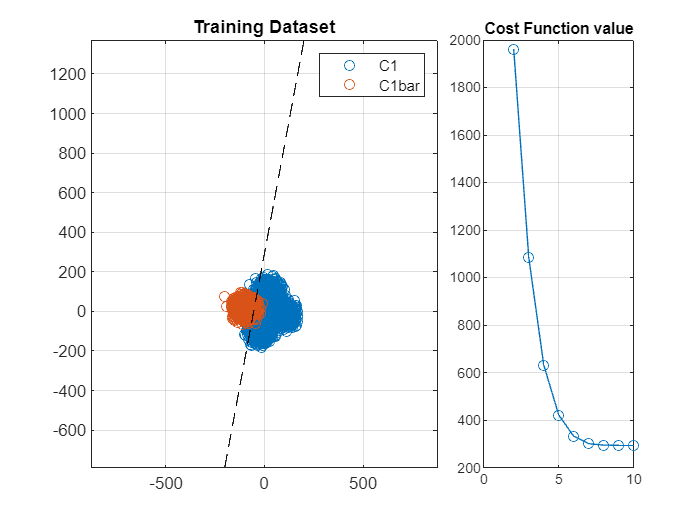

%NEWTON RAPHSON METHOD
%starting point
Ntrain = length(Utrain);
Theta=[0;0;0];
PHITrain=[ones(Ntrain,1) Utrain];
J = myLRCostFunc(PHITrain,YtrainC1,Theta);
J(1)=1000;
delta = 0.001;
k = 2;
alpha = 1; %Step Size is not of particular interest in NR

figure();
while 1 %it loops until the stopping criterion is fullfilled
    
    gradJ = LRCostFuncDeriv(PHITrain,YtrainC1,Theta,1); %gradient of J
    HessJ=LRCostFuncDeriv(PHITrain,YtrainC1,Theta,2); %hessian of J
    Theta = Theta - alpha*inv(HessJ)*gradJ; %update
    J(k)=-myLRCostFunc(PHITrain,YtrainC1,Theta); %loss function J  
    
    %stopping criterion
    if (abs(J(k)-J(k-1))<delta)
        break; %end of the algorithm
    end
    
    %plot
    subplot(1,3,[1 2]);
    plot(Utrain(find(YtrainC1<0.5),1),Utrain(find(YtrainC1<0.5),2),'o');
    hold on 
    grid on 
    plot(Utrain(find(YtrainC1>0.5),1),Utrain(find(YtrainC1>0.5),2),'o');

    %linear decision boundary
    Xlim=xlim();
    xspace = Xlim(1):0.1:Xlim(end);
    BoundaryLine = (Theta(1) + xspace.*Theta(2))./(-Theta(3));
    plot(xspace,BoundaryLine,'--k');
    xlim(Xlim);

    axis equal
    hold off
    title('Training Dataset');
    legend({'C1','C1bar'}); 
    subplot(1,3,3);
    plot(2:k,J(2:k),'o-');
    grid on;
    title('Cost Function value')
    
    pause(0.1);
    k=k+1; %new iteration
    
end

### **3) VERIFY AND TEST YOUR CLASSIFICATOR**

#### **3.1) DEFINITION OF THE M DECISION BOUNDARIES**

Once that the M binary classification problems have been already defined and the iterative algorithm has been chosen, it is possibile to estimate all the models that lead to the M different hyperplanes. To perform estimations, multiple iterations of the Newton-Raphson method have to be used, one for each binary problem. Let's embed the method inside a matlab function, called *Newton-Raphson.m*, which evaluates the paramaters of each hyperplanes. Meanwhile, we can verify the goodness of our model by evaluating it in comparison with the provided logistic regression matlab function **mnrfit():**

%starting point
Ntrain = length(Utrain);
Theta=[0;0;0];
PHITrain=[ones(Ntrain,1) Utrain];
delta = 0.001;
k = 2;
alpha = 1; %Step Size is not of particular interest in NR

%first hyperplane
J = myLRCostFunc(PHITrain,YtrainC1,Theta); J(1)=1000;
ThetaZ1 = NewtonRaphson(YtrainC1,Theta,PHITrain,alpha,delta,J,k);
TrueThetaZ1 = mnrfit(Utrain,YtrainC1+1);
disp([ThetaZ1 TrueThetaZ1]);

   -8.3368    8.3367
   -0.1530    0.1530
    0.0284   -0.0284




%second hyperplane
J = myLRCostFunc(PHITrain,YtrainC2,Theta); J(1)=1000;
ThetaZ2 = NewtonRaphson(YtrainC2,Theta,PHITrain,alpha,delta,J,k);
TrueThetaZ2 = mnrfit(Utrain,YtrainC2+1); 
disp([ThetaZ2 TrueThetaZ2]);

   -8.8041    8.8041
   -0.0275    0.0275
   -0.1590    0.1590




%third hyperplane
J = myLRCostFunc(PHITrain,YtrainC3,Theta); J(1)=1000;
ThetaZ3 = NewtonRaphson(YtrainC3,Theta,PHITrain,alpha,delta,J,k);
TrueThetaZ3 = mnrfit(Utrain,YtrainC3+1); 
disp([ThetaZ3 TrueThetaZ3]);

   -8.6317    8.6318
    0.1538   -0.1538
   -0.0285    0.0285




%fourth hyperplane
J = myLRCostFunc(PHITrain,YtrainC4,Theta); J(1)=1000;
ThetaZ4 = NewtonRaphson(YtrainC4,Theta,PHITrain,alpha,delta,J,k);
TrueThetaZ4 = mnrfit(Utrain,YtrainC4+1); 
disp([ThetaZ4 TrueThetaZ4])

   -8.7465    8.7465
    0.0291   -0.0291
    0.1595   -0.1595



As it can be noticed, they are practically equal in absolute values, therefore the NewtonRaphson method has worked pretty well on the estimation of the optimal hyperplanes' models. 

#### **3.2) MULTI-CLASS PROBLEM'S PLOT IN TRAINING SET**

Let's create now the final plot concerning all the M linear decision boundaries and the relative classes:

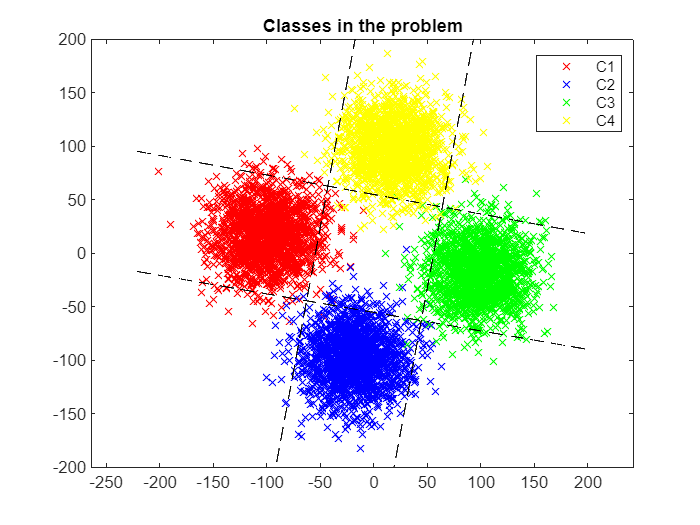

figure();

%data points
figure();
gscatter(Utrain(:,1),Utrain(:,2),Ytrain,'rbgy','x');
hold on

%linear decision boundaries
Xlim=xlim();
Ylim=ylim();
xspace = Xlim(1):0.1:Xlim(end);

BoundaryLineC1 = (ThetaZ1(1) + xspace.*ThetaZ1(2))./(-ThetaZ1(3));
plot(xspace,BoundaryLineC1,'--k');

BoundaryLineC2 = (ThetaZ2(1) + xspace.*ThetaZ2(2))./(-ThetaZ2(3));
plot(xspace,BoundaryLineC2,'--k');

BoundaryLineC3 = (ThetaZ3(1) + xspace.*ThetaZ3(2))./(-ThetaZ3(3));
plot(xspace,BoundaryLineC3,'--k');

BoundaryLineC4 = (ThetaZ4(1) + xspace.*ThetaZ4(2))./(-ThetaZ4(3));
plot(xspace,BoundaryLineC4,'--k');

xlim(Xlim);
ylim(Ylim);

hold off
title('Classes in the problem');
legend({'C1','C2','C3','C4'});
axis equal

**3.2) MULTI-CLASS PROBLEM'S PLOT IN TEST SET & CLASSIFICATION ERROR**

The goal now would be to challenge the classificator on unseen data, contained inside the test set. Those points, in fact, have not been used for the estimation of the hyperplane, for this reason they play the role of future unseen data for the classificator. Hence, we use the previously computed hyperplanes to perform predictions, we use the Logistic Sigmoid function to compute the probabilities and properly assign classes to each input:

Ntest = length(Utest); %number of points of the test set
PHITest=[ones(Ntest,1) Utest];

%estimation of posterior probabilities
YhatC1 = Sigmoid(PHITest*ThetaZ1); YhatC1 = double(YhatC1>0.5);
YhatC2 = Sigmoid(PHITest*ThetaZ2); YhatC2 = double(YhatC2>0.5);
YhatC3 = Sigmoid(PHITest*ThetaZ3); YhatC3 = double(YhatC3>0.5);
YhatC4 = Sigmoid(PHITest*ThetaZ4); YhatC4 = double(YhatC4>0.5);

%binary classification problems for test set
YtestC1 = binaryClassification(Ytest,Utest,1);
YtestC2 = binaryClassification(Ytest,Utest,2);
YtestC3 = binaryClassification(Ytest,Utest,3);
YtestC4 = binaryClassification(Ytest,Utest,4);

%classification errors for Test-Set
ClassificationErrorC1 = 1/(Ntest)*((abs(YhatC1-YtestC1))'*(abs(YhatC1-YtestC1)))

ClassificationErrorC1 = 0.0207

ClassificationErrorC2 = 1/(Ntest)*((abs(YhatC2-YtestC2))'*(abs(YhatC2-YtestC2)))

ClassificationErrorC2 = 0.0177

ClassificationErrorC3 = 1/(Ntest)*((abs(YhatC3-YtestC3))'*(abs(YhatC3-YtestC3)))

ClassificationErrorC3 = 0.0177

ClassificationErrorC4 = 1/(Ntest)*((abs(YhatC4-YtestC4))'*(abs(YhatC4-YtestC4)))

ClassificationErrorC4 = 0.0143

Classification errors turn out to be really small thanks to the excellent job that has been performed by the estimation algorithm. In fact, Netwon-Raphson method is one of the most accurate optimization algorithm, because of the presence of the hessian matrix. This latter, in fact, is able to guide the algorithm to the optimal solution. Let's take a look at the plot with both real and estimated values by means of the hyperplane, it could make things clearer:

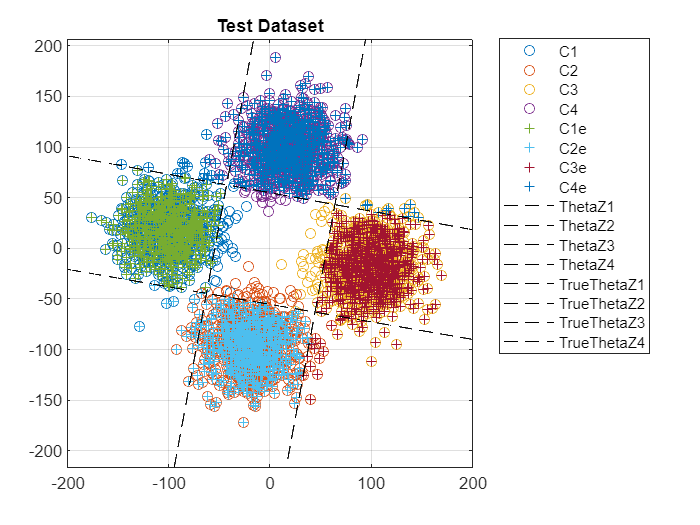

figure();
%actual data-set points
plot(Utest(find(YtestC1>0.5),1),Utest(find(YtestC1>0.5),2),'o');
hold on 
grid on 
plot(Utest(find(YtestC2>0.5),1),Utest(find(YtestC2>0.5),2),'o');
plot(Utest(find(YtestC3>0.5),1),Utest(find(YtestC3>0.5),2),'o');
plot(Utest(find(YtestC4>0.5),1),Utest(find(YtestC4>0.5),2),'o');

%estimated data-set points
plot(Utest(find(YhatC1>0.5),1),Utest(find(YhatC1>0.5),2),'+');
plot(Utest(find(YhatC2>0.5),1),Utest(find(YhatC2>0.5),2),'+');
plot(Utest(find(YhatC3>0.5),1),Utest(find(YhatC3>0.5),2),'+');
plot(Utest(find(YhatC4>0.5),1),Utest(find(YhatC4>0.5),2),'+');

%plot's limits
Xlim=xlim();
Ylim=ylim();
xspace = Xlim(1):0.1:Xlim(end);

%estimated linear decision boundaries of the data-set
BoundaryLineC1 = (ThetaZ1(1) + xspace.*ThetaZ1(2))./(-ThetaZ1(3));
plot(xspace,BoundaryLineC1,'--k');
BoundaryLineC2 = (ThetaZ2(1) + xspace.*ThetaZ2(2))./(-ThetaZ2(3));
plot(xspace,BoundaryLineC2,'--k');
BoundaryLineC3 = (ThetaZ3(1) + xspace.*ThetaZ3(2))./(-ThetaZ3(3));
plot(xspace,BoundaryLineC3,'--k');
BoundaryLineC4 = (ThetaZ4(1) + xspace.*ThetaZ4(2))./(-ThetaZ4(3));
plot(xspace,BoundaryLineC4,'--k');

%true linear decision boundaries of the data-set
TrueBoundaryLineC1 = (TrueThetaZ1(1) + xspace.*TrueThetaZ1(2))./(-TrueThetaZ1(3));
plot(xspace,TrueBoundaryLineC1,'--k');
TrueBoundaryLineC2 = (TrueThetaZ2(1) + xspace.*TrueThetaZ2(2))./(-TrueThetaZ2(3));
plot(xspace,TrueBoundaryLineC2,'--k');
TrueBoundaryLineC3 = (TrueThetaZ3(1) + xspace.*TrueThetaZ3(2))./(-TrueThetaZ3(3));
plot(xspace,TrueBoundaryLineC3,'--k');
TrueBoundaryLineC4 = (TrueThetaZ4(1) + xspace.*TrueThetaZ4(2))./(-TrueThetaZ4(3));
plot(xspace,TrueBoundaryLineC4,'--k');

xlim(Xlim);
ylim(Ylim);

hold off
Title =  sprintf('Test Dataset');
title(Title);
legend({'C1','C2','C3','C4','C1e','C2e','C3e','C4e','ThetaZ1','ThetaZ2','ThetaZ3','ThetaZ4','TrueThetaZ1','TrueThetaZ2','TrueThetaZ3','TrueThetaZ4'},'location','bestoutside');
axis equal

From the previous plot we can immediatly notice that the errors that have been made in the estimation of the decision boundaries are negligible, thanks to the good job performed by the Newton-Raphson method, therefore the overall clssification turns out to be a piece of cake for the implemented logistic regression classifier.